# **Exercise 5.1 (MathematicalModel).**

clc;
clear;

load('param.mat')
param.x0 = [pi,0,0,0].';

syms g
% For the spring
syms l_c l_ax l_ay k_t s_0 
% For the beam
syms m_B1 m_B2 l_B1 l_B2 
% For the Platform 
syms J_Pzz d_P
% For the Motor
syms R_m k_b k_m K_g eta_g eta_m nu k_r 

**(i) Determine the moment of inertia of the entire beam **$J_{B,zz}$** , which can be approximated as a rod, based on the data given in Tab. 5.1. Use the parallel axis theorem. Furthermore, calculate the value **$l_G$**. **

% Moment of intertia of the first rod (about the center of mass)
Icm_1 = 1/12*(m_B1*(l_B1^2)); 
% Moment of inertia of the second rod (about the center of mass)
Icm_2 = 1/12*(m_B2*(l_B2^2));

% Total moment of inertia (about z-axis) using parallel axis theorem
J_Bzz = Icm_1 + m_B1*((l_B1/2)^2) + Icm_2 + m_B2*((l_B1-l_B2/2)^2)

$$J\_Bzz = \frac{{l_{\mathrm{B1}}}^{2}\,m_{\mathrm{B1}}}{3}+\frac{{l_{\mathrm{B2}}}^{2}\,m_{\mathrm{B2}}}{12}+m_{\mathrm{B2}}\,{\left(l_{\mathrm{B1}}-\frac{l_{\mathrm{B2}}}{2}\right)}^{2}$$


% The center of gravity of the two rods
l_G = ( m_B1*(l_B1/2) + m_B2*(l_B1-l_B2/2) )/(m_B1 + m_B2)

$$l\_G = \frac{\frac{l_{\mathrm{B1}}\,m_{\mathrm{B1}}}{2}+m_{\mathrm{B2}}\,\left(l_{\mathrm{B1}}-\frac{l_{\mathrm{B2}}}{2}\right)}{m_{\mathrm{B1}}+m_{\mathrm{B2}}}$$


% Substitue with the given data
J_Bzz_val = subs(J_Bzz, [m_B1, m_B2, l_B1, l_B2], ...
    [param.m_B1, param.m_B2, param.l_B1, param.l_B2]);
J_Bzz_val = vpa(J_Bzz_val,3)

$$J\_Bzz\_val = 0.00341$$


l_G_val = subs(l_G, [m_B1, m_B2, l_B1, l_B2], ...
    [param.m_B1, param.m_B2, param.l_B1, param.l_B2]);
l_G_val = vpa(l_G_val,3)

$$l\_G\_val = 0.172$$


clear J_Bzz l_G

**(ii) Determine the rotary flexible joint’s two sets of equations of motion using the Lagrange formalism and the Matlab symbolic toolbox. **

**Describe the system(s) in the form**

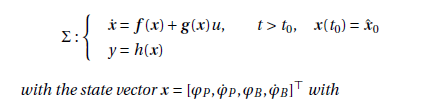

**a) the potential energy given by (5.2) (simulation model).**

**b) the potential energy given by (5.4) (control model).**

% Generalized coordinates
syms phi_P(t) phi_B(t) u k_f J_Bzz l_G
q = [phi_P(t); phi_B(t);];
q_dot = diff(q,t);

Coordinate transformations ( for notation $R_0^P$ = R_P0 )

% Rotation around the Z axis
rot_z = @(angle) [ cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1; ];

% Rotation transformations
R_P0 = rot_z(phi_P);
R_BP = rot_z(phi_B);
R_B0 = rot_z(phi_P + phi_B);

p_aP = [ l_ax; -l_ay; 0; ];
p_bP = [ l_ax; l_ay; 0; ];
p_cB = [ l_c; 0; 0; ];

p_a0 = R_P0*p_aP;  
p_b0 = R_P0*p_bP;
p_c0 = R_B0*p_cB;

p_cP = R_BP*p_cB;

a)

Potential energy (for the simulation model)

delta_s1 = sqrt(transpose(p_cP - p_aP)*(p_cP - p_aP)) - s_0;
delta_s2 = sqrt(transpose(p_cP - p_bP)*(p_cP - p_bP)) - s_0;

E_sim_pot = 0.5*k_f*(delta_s1^2 + delta_s2^2) + ...
    (m_B1+m_B2)*g*l_G*cos(phi_P + phi_B)

$$E\_sim\_pot(t) = \frac{k_{f}\,\left({\left(s_{0}-\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(\varphi_{B}\left(t\right)\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(\varphi_{B}\left(t\right)\right)\right)}^{2}}\right)}^{2}+{\left(s_{0}-\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(\varphi_{B}\left(t\right)\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(\varphi_{B}\left(t\right)\right)\right)}^{2}}\right)}^{2}\right)}{2}+g\,l_{G}\,\cos\left(\varphi_{B}\left(t\right)+\varphi_{P}\left(t\right)\right)\,\left(m_{\mathrm{B1}}+m_{\mathrm{B2}}\right)$$

Kinetic energy

E_kin = 0.5*J_Pzz*q_dot(1)^2 + 0.5*J_Bzz*(q_dot(1) + q_dot(2))^2;

Dissipation

R = 0.5*d_P*(q_dot(1)^2);

For the DC Motor and generalized forces

v = k_b*K_g*eta_m*eta_g;
Q_nc1 = v*((u - k_m*q_dot(1))/R_m);
Q_nc2 = 0;
Q_nc = [ Q_nc1; Q_nc2];

Lagrangian

L = E_kin - E_sim_pot;
e1 = simplify(diff(diff(L, q_dot(1)),t) - diff(L,q(1)) + diff(R, q_dot(1)) - Q_nc1) == 0;
e2 = simplify(diff(diff(L, q_dot(2)),t) - diff(L,q(2)) + diff(R, q_dot(2)) - Q_nc2) == 0;

Isolating

h1 = diff(q_dot(1),t) == simplify(rhs(isolate(e1, diff(q_dot(1),t))));
h2 = diff(q_dot(2),t) == simplify(rhs(isolate(e2, diff(q_dot(2),t))));

dd_phiP = diff(q_dot(1),t) == simplify(rhs(isolate(subs(h1, lhs(h2), rhs(h2)), diff(q_dot(1),t))))

$$dd\_phiP = \frac{\partial^{2}}{\partial t^{2}}\varphi_{P}\left(t\right)=-\frac{d_{P}\,\frac{\partial }{\partial t}\varphi_{P}\left(t\right)-2\,k_{f}\,l_{\mathrm{ax}}\,l_{c}\,\sin\left(\varphi_{B}\left(t\right)\right)-\frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,u}{R_{m}}+\frac{k_{f}\,l_{\mathrm{ay}}\,l_{c}\,s_{0}\,\cos\left(\varphi_{B}\left(t\right)\right)}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(\varphi_{B}\left(t\right)\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(\varphi_{B}\left(t\right)\right)\right)}^{2}}}-\frac{k_{f}\,l_{\mathrm{ay}}\,l_{c}\,s_{0}\,\cos\left(\varphi_{B}\left(t\right)\right)}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(\varphi_{B}\left(t\right)\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(\varphi_{B}\left(t\right)\right)\right)}^{2}}}+\frac{k_{f}\,l_{\mathrm{ax}}\,l_{c}\,s_{0}\,\sin\left(\varphi_{B}\left(t\right)\right)}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(\varphi_{B}\left(t\right)\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(\varphi_{B}\left(t\right)\right)\right)}^{2}}}+\frac{k_{f}\,l_{\mathrm{ax}}\,l_{c}\,s_{0}\,\sin\left(\varphi_{B}\left(t\right)\right)}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(\varphi_{B}\left(t\right)\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(\varphi_{B}\left(t\right)\right)\right)}^{2}}}+\frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,k_{m}\,\frac{\partial }{\partial t}\varphi_{P}\left(t\right)}{R_{m}}}{J_{\mathrm{Pzz}}}$$

dd_phiB = diff(q_dot(2),t) == simplify(rhs(isolate(subs(h2, lhs(dd_phiP), rhs(dd_phiP)), diff(q_dot(2),t))))

Describe the system in the required form

syms x1 x2 x3 x4
% x
x = [x1; x2; x3; x4];
% f(x)
f1 = x2;
f3 = x4;

f2 = subs(rhs(dd_phiP),[q_dot(1),q_dot(2),q(1),q(2),u],[x2,x4,x1,x3,0]); % the order to substitute is important
f2 = simplify(f2,'IgnoreAnalyticConstraints',true);
f2 = collect(f2,[sin(x3),cos(x3),x2,sin(x1+x3)]) % Collect coefficients in terms of x

$$f2 = \left(-\frac{\frac{k_{f}\,l_{\mathrm{ax}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}-2\,k_{f}\,l_{\mathrm{ax}}\,l_{c}+\frac{k_{f}\,l_{\mathrm{ax}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}}{J_{\mathrm{Pzz}}}\right)\,\sin\left(x_{3}\right)+\left(-\frac{\frac{k_{f}\,l_{\mathrm{ay}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}-\frac{k_{f}\,l_{\mathrm{ay}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}}{J_{\mathrm{Pzz}}}\right)\,\cos\left(x_{3}\right)+\left(-\frac{d_{P}+\frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,k_{m}}{R_{m}}}{J_{\mathrm{Pzz}}}\right)\,x_{2}$$


f4 = subs(rhs(dd_phiB),[q_dot(1),q_dot(2),q(1),q(2),u],[x2,x4,x1,x3,0]);
f4 = simplify(f4,'IgnoreAnalyticConstraints',true);
f4 = collect(f4,[sin(x1+x3),sin(x3),cos(x3)]) 

$$f4 = \frac{g\,l_{G}\,m_{\mathrm{B1}}+g\,l_{G}\,m_{\mathrm{B2}}}{J_{\mathrm{Bzz}}}\,\sin\left(x_{1}+x_{3}\right)+\frac{\frac{J_{\mathrm{Bzz}}\,\left(\frac{k_{f}\,l_{\mathrm{ax}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}-2\,k_{f}\,l_{\mathrm{ax}}\,l_{c}+\frac{k_{f}\,l_{\mathrm{ax}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}\right)}{J_{\mathrm{Pzz}}}-2\,k_{f}\,l_{\mathrm{ax}}\,l_{c}+\frac{k_{f}\,l_{\mathrm{ax}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}+\frac{k_{f}\,l_{\mathrm{ax}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}}{J_{\mathrm{Bzz}}}\,\sin\left(x_{3}\right)+\frac{\frac{J_{\mathrm{Bzz}}\,\left(\frac{k_{f}\,l_{\mathrm{ay}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}-\frac{k_{f}\,l_{\mathrm{ay}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}\right)}{J_{\mathrm{Pzz}}}+\frac{k_{f}\,l_{\mathrm{ay}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}+l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}-\frac{k_{f}\,l_{\mathrm{ay}}\,l_{c}\,s_{0}}{\sqrt{{\left(l_{\mathrm{ax}}-l_{c}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(l_{\mathrm{ay}}-l_{c}\,\sin\left(x_{3}\right)\right)}^{2}}}}{J_{\mathrm{Bzz}}}\,\cos\left(x_{3}\right)+\frac{d_{P}\,x_{2}+\frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,k_{m}\,x_{2}}{R_{m}}}{J_{\mathrm{Pzz}}}$$


f = [ f1; f2; f3; f4 ];
% g(x)
g1 = 0;
g3 = 0;

g2 = subs(rhs(dd_phiP),[q_dot(1),q_dot(2),q(1),q(2)],[0,0,0,0]);
g2 = subs(g2,u,1);

g4 = subs(rhs(dd_phiB),[q_dot(1),q_dot(2),q(1),q(2)],[0,0,0,0]);
g4 = simplify(subs(g4,u,1));

gx = [ g1; g2; g3; g4 ]

$$gx = \left(\begin{array}{c} 0\\ \frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}}{J_{\mathrm{Pzz}}\,R_{m}}\\ 0\\ -\frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}}{J_{\mathrm{Pzz}}\,R_{m}} \end{array}\right)$$

% h(x)
h = x1 + x3

$$h = x_{1}+x_{3}$$

b)

Potential energy (for the control model)

E_ctrl_pot = 0.5*k_r*phi_B^2 + (m_B1+m_B2)*g*l_G*cos(phi_P + phi_B)

$$E\_ctrl\_pot(t) = \frac{k_{r}\,{\varphi_{B}\left(t\right)}^{2}}{2}+g\,l_{G}\,\cos\left(\varphi_{B}\left(t\right)+\varphi_{P}\left(t\right)\right)\,\left(m_{\mathrm{B1}}+m_{\mathrm{B2}}\right)$$

Lagrangian

clear L e1 e2 h1 h2 dd_phiP dd_phiB
L = E_kin - E_ctrl_pot;
e1 = simplify(diff(diff(L, q_dot(1)),t) - diff(L,q(1)) + diff(R, q_dot(1)) - Q_nc1) == 0;
e2 = simplify(diff(diff(L, q_dot(2)),t) - diff(L,q(2)) + diff(R, q_dot(2)) - Q_nc2) == 0;

Isolating

h1 = diff(q_dot(1),t) == simplify(rhs(isolate(e1, diff(q_dot(1),t))));
h2 = diff(q_dot(2),t) == simplify(rhs(isolate(e2, diff(q_dot(2),t))));

dd_phiP = diff(q_dot(1),t) == simplify(rhs(isolate(subs(h1, lhs(h2), rhs(h2)), diff(q_dot(1),t))))

$$dd\_phiP = \frac{\partial^{2}}{\partial t^{2}}\varphi_{P}\left(t\right)=\frac{R_{m}\,k_{r}\,\varphi_{B}\left(t\right)-R_{m}\,d_{P}\,\frac{\partial }{\partial t}\varphi_{P}\left(t\right)+K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,u-K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,k_{m}\,\frac{\partial }{\partial t}\varphi_{P}\left(t\right)}{J_{\mathrm{Pzz}}\,R_{m}}$$

dd_phiB = diff(q_dot(2),t) == simplify(rhs(isolate(subs(h2, lhs(dd_phiP), rhs(dd_phiP)), diff(q_dot(2),t))))

$$dd\_phiB = \frac{\partial^{2}}{\partial t^{2}}\varphi_{B}\left(t\right)=-\frac{k_{r}\,\varphi_{B}\left(t\right)-g\,l_{G}\,\sin\left(\varphi_{B}\left(t\right)+\varphi_{P}\left(t\right)\right)\,\left(m_{\mathrm{B1}}+m_{\mathrm{B2}}\right)+\frac{J_{\mathrm{Bzz}}\,\left(R_{m}\,k_{r}\,\varphi_{B}\left(t\right)-R_{m}\,d_{P}\,\frac{\partial }{\partial t}\varphi_{P}\left(t\right)+K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,u-K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,k_{m}\,\frac{\partial }{\partial t}\varphi_{P}\left(t\right)\right)}{J_{\mathrm{Pzz}}\,R_{m}}}{J_{\mathrm{Bzz}}}$$

Describe the system in the required form

clear f gx
% f(x)
f2 = subs(rhs(dd_phiP),[q_dot(1),q_dot(2),q(1),q(2),u],[x2,x4,x1,x3,0]); % the order to substitute is important
f2 = collect(f2,x); % Collect coefficients in terms of x

f4 = subs(rhs(dd_phiB),[q_dot(1),q_dot(2),q(1),q(2),u],[x2,x4,x1,x3,0]);
f4 = simplify(collect(f4,x));
f4 = collect(f4,sin(x1+x3)); % Collect coefficients in terms of "sin"

f = [ f1; f2; f3; f4 ]

$$f = \left(\begin{array}{c} x_{2}\\ \left(-\frac{R_{m}\,d_{P}+K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,k_{m}}{J_{\mathrm{Pzz}}\,R_{m}}\right)\,x_{2}+\frac{k_{r}}{J_{\mathrm{Pzz}}}\,x_{3}\\ x_{4}\\ \frac{g\,l_{G}\,\left(m_{\mathrm{B1}}+m_{\mathrm{B2}}\right)}{J_{\mathrm{Bzz}}}\,\sin\left(x_{1}+x_{3}\right)+\frac{x_{2}\,\left(R_{m}\,d_{P}+K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,k_{m}\right)}{J_{\mathrm{Pzz}}\,R_{m}}-\frac{k_{r}\,x_{3}\,\left(J_{\mathrm{Bzz}}+J_{\mathrm{Pzz}}\right)}{J_{\mathrm{Bzz}}\,J_{\mathrm{Pzz}}} \end{array}\right)$$

% g(x)
g2 = subs(rhs(dd_phiP),[q_dot(1),q_dot(2),q(1),q(2)],[0,0,0,0]);
g2 = subs(g2,u,1);

g4 = subs(rhs(dd_phiB),[q_dot(1),q_dot(2),q(1),q(2)],[0,0,0,0]);
g4 = simplify(subs(g4,u,1));

gx = [ g1; g2; g3; g4 ]

$$gx = \left(\begin{array}{c} 0\\ \frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}}{J_{\mathrm{Pzz}}\,R_{m}}\\ 0\\ -\frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}}{J_{\mathrm{Pzz}}\,R_{m}} \end{array}\right)$$

**(v)**

For the sake of illustration, here we solve **question (v)** first:

Determine the relative degree `r`.

k = 0;
lglfh = Lfh(gx,Lfh(f,h,x,0),x,1)

$$lglfh = 0$$

while lglfh == 0
    k = k+1;
    lglfh = simplify( Lfh(gx,Lfh(f,h,x,k),x,1) ) % eq(3.9)
end

$$lglfh = 0$$

$$lglfh = 0$$

$$lglfh = \frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{b}\,k_{r}}{J_{\mathrm{Bzz}}\,J_{\mathrm{Pzz}}\,R_{m}}$$


r = k+1 % k=r-1

r = 4

The relative degree of the output `y=λ``(``x``)` is `r=n=``4`, for SISO case it hence is the necessary and suffificient for the flatness of the nonlinear system.

Transformation `θ``x`

% Flat output
syms lambda(t)
d_lambda = diff(lambda,t)

$$d\_lambda(t) = \frac{\partial }{\partial t}\lambda \left(t\right)$$

dd_lambda = diff(d_lambda,t)

$$dd\_lambda(t) = \frac{\partial^{2}}{\partial t^{2}}\lambda \left(t\right)$$

ddd_lambda = diff(dd_lambda,t)

$$ddd\_lambda(t) = \frac{\partial^{3}}{\partial t^{3}}\lambda \left(t\right)$$

% Time–derivatives of lambda in terms of x
eq1 = lambda == Lfh(f,h,x,0)

$$eq1(t) = \lambda \left(t\right)=x_{1}+x_{3}$$

eq2 = d_lambda == Lfh(f,h,x,1)

$$eq2(t) = \frac{\partial }{\partial t}\lambda \left(t\right)=x_{2}+x_{4}$$


eq3 = dd_lambda == collect( simplify(Lfh(f,h,x,2)), x3 );
eq3 = subs(eq3, x1+x3, lambda)

$$eq3(t) = \frac{\partial^{2}}{\partial t^{2}}\lambda \left(t\right)=\frac{g\,l_{G}\,m_{\mathrm{B1}}\,\sin\left(\lambda \left(t\right)\right)+g\,l_{G}\,m_{\mathrm{B2}}\,\sin\left(\lambda \left(t\right)\right)}{J_{\mathrm{Bzz}}}-\frac{k_{r}\,x_{3}}{J_{\mathrm{Bzz}}}$$


eq4 = ddd_lambda == simplify(Lfh(f,h,x,3));
eq4 = collect( subs(eq4, x1+x3, lambda), x )

$$eq4(t) = \frac{\partial^{3}}{\partial t^{3}}\lambda \left(t\right)=\frac{g\,l_{G}\,\cos\left(\lambda \left(t\right)\right)\,\left(m_{\mathrm{B1}}+m_{\mathrm{B2}}\right)}{J_{\mathrm{Bzz}}}\,x_{2}+\frac{g\,l_{G}\,m_{\mathrm{B1}}\,\cos\left(\lambda \left(t\right)\right)-k_{r}+g\,l_{G}\,m_{\mathrm{B2}}\,\cos\left(\lambda \left(t\right)\right)}{J_{\mathrm{Bzz}}}\,x_{4}$$

% Solve the system of non-linear equations
sol = solve([eq1,eq2,eq3,eq4],[x1, x2, x3, x4])

sol = struct with fields:
    x1: (J_Bzz*diff(lambda(t), t, t) + k_r*lambda(t) - g*l_G*m_B1*sin(lambda(t)) - g*l_G*m_B2*sin(lambda(t)))/k_r
    x2: (J_Bzz*diff(lambda(t), t, t, t) + k_r*diff(lambda(t), t) - g*l_G*m_B1*cos(lambda(t))*diff(lambda(t), t) - g*l_G*m_B2*cos(lambda(t))*diff(lambda(t), t))/k_r
    x3: (g*l_G*m_B1*sin(lambda(t)) - J_Bzz*diff(lambda(t), t, t) + g*l_G*m_B2*sin(lambda(t)))/k_r
    x4: (g*l_G*m_B1*cos(lambda(t))*diff(lambda(t), t) - J_Bzz*diff(lambda(t), t, t, t) + g*l_G*m_B2*cos(lambda(t))*diff(lambda(t), t))/k_r


% Get theta_x
theta_x1 = sol.x1;
theta_x1 = collect(theta_x1,[lambda,d_lambda,dd_lambda,ddd_lambda,sin(lambda)])

$$theta\_x1 = \lambda \left(t\right)+\frac{J_{\mathrm{Bzz}}}{k_{r}}\,\frac{\partial^{2}}{\partial t^{2}}\lambda \left(t\right)+\left(-\frac{g\,l_{G}\,m_{\mathrm{B1}}+g\,l_{G}\,m_{\mathrm{B2}}}{k_{r}}\right)\,\sin\left(\lambda \left(t\right)\right)$$

theta_x2 = sol.x2;
theta_x2 = collect(theta_x2,[lambda,d_lambda,dd_lambda,ddd_lambda,cos(lambda)])

$$theta\_x2 = \left(-\frac{g\,l_{G}\,m_{\mathrm{B1}}+g\,l_{G}\,m_{\mathrm{B2}}}{k_{r}}\right)\,\frac{\partial }{\partial t}\lambda \left(t\right)\,\cos\left(\lambda \left(t\right)\right)+\frac{\partial }{\partial t}\lambda \left(t\right)+\frac{J_{\mathrm{Bzz}}}{k_{r}}\,\frac{\partial^{3}}{\partial t^{3}}\lambda \left(t\right)$$

theta_x3 = sol.x3;
theta_x3 = collect(theta_x3,[lambda,d_lambda,dd_lambda,ddd_lambda,sin(lambda)])

$$theta\_x3 = \left(-\frac{J_{\mathrm{Bzz}}}{k_{r}}\right)\,\frac{\partial^{2}}{\partial t^{2}}\lambda \left(t\right)+\frac{g\,l_{G}\,m_{\mathrm{B1}}+g\,l_{G}\,m_{\mathrm{B2}}}{k_{r}}\,\sin\left(\lambda \left(t\right)\right)$$

theta_x4 = sol.x4;
theta_x4 = collect(theta_x4,[lambda,d_lambda,dd_lambda,ddd_lambda,cos(lambda)])

$$theta\_x4 = \frac{g\,l_{G}\,m_{\mathrm{B1}}+g\,l_{G}\,m_{\mathrm{B2}}}{k_{r}}\,\frac{\partial }{\partial t}\lambda \left(t\right)\,\cos\left(\lambda \left(t\right)\right)+\left(-\frac{J_{\mathrm{Bzz}}}{k_{r}}\right)\,\frac{\partial^{3}}{\partial t^{3}}\lambda \left(t\right)$$

Transformation `θ``u`

d4_lambda = diff(ddd_lambda,t);
eq5 = d4_lambda == lglfh*u + simplify(Lfh(f,h,x,4));
eq5 = subs(eq5,[x1+x3, x2+x4, x1,x2,x3,x4], ...
    [lambda,d_lambda,theta_x1,theta_x2,theta_x3,theta_x4]); % substitute x with theta_x in terms of lambda
theta_u = solve(eq5,u);
theta_u = collect(theta_u, ...
    [lambda,d_lambda,dd_lambda,ddd_lambda,d4_lambda,sin(lambda),cos(lambda)])

**(iii)**

Now we come back to **question (iii)**

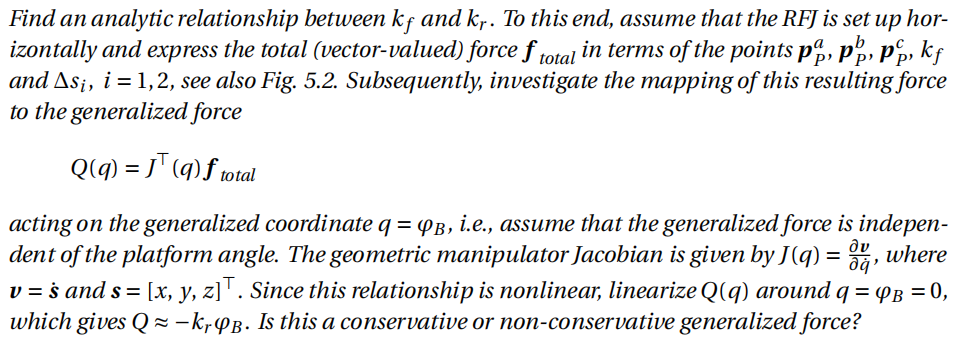

% State positive symbolic variables
assume([l_ay, l_c] > 0)
% Velocity of point c w.r.t. the platform
% (assume that the generalized force is independent of the platform angle)
v_cP = diff(p_cP, t);
% Geometric manipulator Jacobian
J_q2 = jacobian(v_cP,q_dot(2));
% The generalized force acting on q_2
f_total = k_f*( delta_s1*(p_aP-p_cP)./norm(p_aP-p_cP) + delta_s2*(p_bP-p_cP)./norm(p_bP-p_cP) );
Q2 = transpose(J_q2)*f_total;
% Linearization around 0
dQ2 = diff(Q2, phi_B);
dQ2 = subs(dQ2,phi_B,0);
k_r = -dQ2

$$k\_r(t) = k_{f}\,l_{c}\,\left(\frac{2\,{l_{\mathrm{ay}}}^{2}\,l_{c}\,\left(s_{0}-\sqrt{{l_{\mathrm{ay}}}^{2}+{\left(l_{\mathrm{ax}}-l_{c}\right)}^{2}}\right)}{{\left({l_{\mathrm{ay}}}^{2}+{\left|l_{\mathrm{ax}}-l_{c}\right|}^{2}\right)}^{3/2}}-\frac{2\,l_{c}\,\left(s_{0}-\sqrt{{l_{\mathrm{ay}}}^{2}+{\left(l_{\mathrm{ax}}-l_{c}\right)}^{2}}\right)}{\sqrt{{l_{\mathrm{ay}}}^{2}+{\left|l_{\mathrm{ax}}-l_{c}\right|}^{2}}}+\frac{2\,{l_{\mathrm{ay}}}^{2}\,l_{c}}{\sqrt{{l_{\mathrm{ay}}}^{2}+{\left(l_{\mathrm{ax}}-l_{c}\right)}^{2}}\,\sqrt{{l_{\mathrm{ay}}}^{2}+{\left|l_{\mathrm{ax}}-l_{c}\right|}^{2}}}\right)-\frac{2\,k_{f}\,l_{c}\,\left(l_{\mathrm{ax}}-l_{c}\right)\,\left(s_{0}-\sqrt{{l_{\mathrm{ay}}}^{2}+{\left(l_{\mathrm{ax}}-l_{c}\right)}^{2}}\right)}{\sqrt{{l_{\mathrm{ay}}}^{2}+{\left|l_{\mathrm{ax}}-l_{c}\right|}^{2}}}$$

k_r = subs(k_r, [k_f,l_c,s_0,l_ay,l_ax], [param.k_t, param.l_c, param.s_0, param.l_ay, param.l_ax]);
k_r = vpa(k_r,4)

$$k\_r(t) = 0.3959$$

Since this force is solely dependent on the initial and final angular positions of the beam, i.e. the work done by the force does not depend on the path taken by the beam, it's a conservative force.

(**iv) Compare the value obtained using the analytic relationship from the previous task to an empirically-obtained value of kr. To this end, calculate kr using the relationship kr ≈ ω20JB,zz , where the natural frequency ω0 can be obtained by means of the power spectral density**

**of the impulse response provided in the file rfj_impulse_response.mat.**

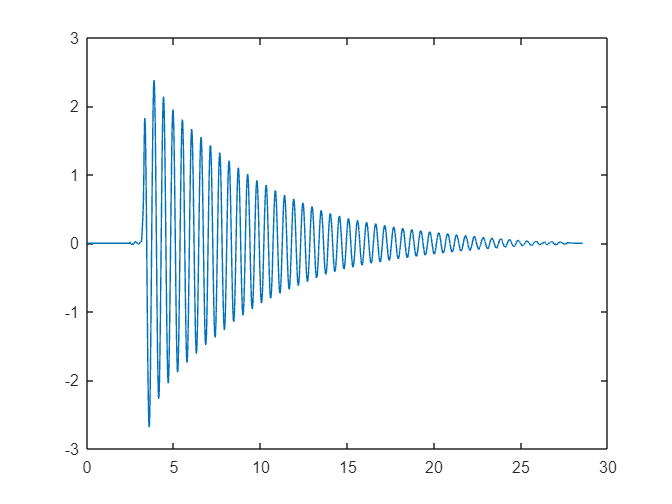

load('rfj_impulse_response.mat')
plot( rfj_impulse_response.time, rfj_impulse_response.varphi_B )


% Fast fourier transform
FFT_phiB = fft(rfj_impulse_response.varphi_B);

% Get the sampling frequency
dt = rfj_impulse_response.time(end) - rfj_impulse_response.time(end-1);
fs = 1/dt;

% Get the number of samples
L = length(rfj_impulse_response.time);

% Power spectrum
Syy = abs(FFT_phiB)/L;
P1 = Syy(1:L/2+1); % single-sided spectrum

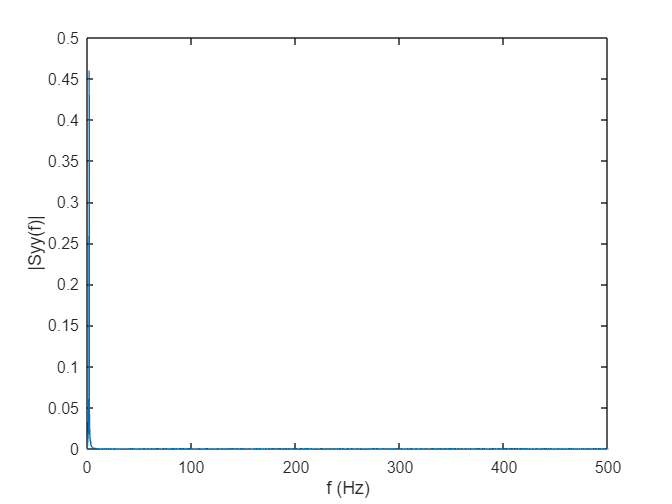

P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L;
plot(f,P1)
xlabel("f (Hz)")
ylabel("|Syy(f)|")


% Identify the peak in the PSD curve
[maxSyy,index] = max(P1);
% w_0 is the frequency at which the PSD is highest.
w_0 = 2*pi*f(index);

k_r = w_0^2*J_Bzz_val;
k_r = vpa(k_r,4)

$$k\_r = 0.4813$$

Based on the results of the two calculations, it can be seen that they have different values, but are in the same order of magnitude. This shows that the two approximations corroborate each other's correctness.